n_in = 256;
freq1 = 0.01;
freq2 = 0.1;
freq3 = 0.4;
nv = 0:(n_in-1);
xi = nv*0; xi(1) = 1; %impulse input
xs = square((nv*2*pi)/256);
x3 = cos(2*pi*freq1*nv);
x4 = cos(2*pi*freq2*nv);
x5 = cos(2*pi*freq3*nv);

% Section 3

a1 = [1.0, -0.9];
b1 = 1;

y1 = filter(b1, a1, xi)

y1 =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351    0.1216    0.1094    0.0985    0.0886    0.0798    0.0718    0.0646    0.0581    0.0523    0.0471    0.0424    0.0382    0.0343    0.0309    0.0278    0.0250    0.0225    0.0203    0.0182    0.0164    0.0148    0.0133    0.0120    0.0108    0.0097    0.0087    0.0079    0.0071    0.0064    0.0057



%We expect y1[1] = 1, y1[2] = 0.9, y1[3] = 0.81

a2 = [1.0, 0.9];
b2 = 1;

y2 =  filter(b2, a2, xi);

%we expect y2[1] = 1, y2[2] = -0.9, y[3] = 0.81
 
% Square response
y3 = filter(b1, a1, xs);
y4 =  filter(b2, a2, xs);


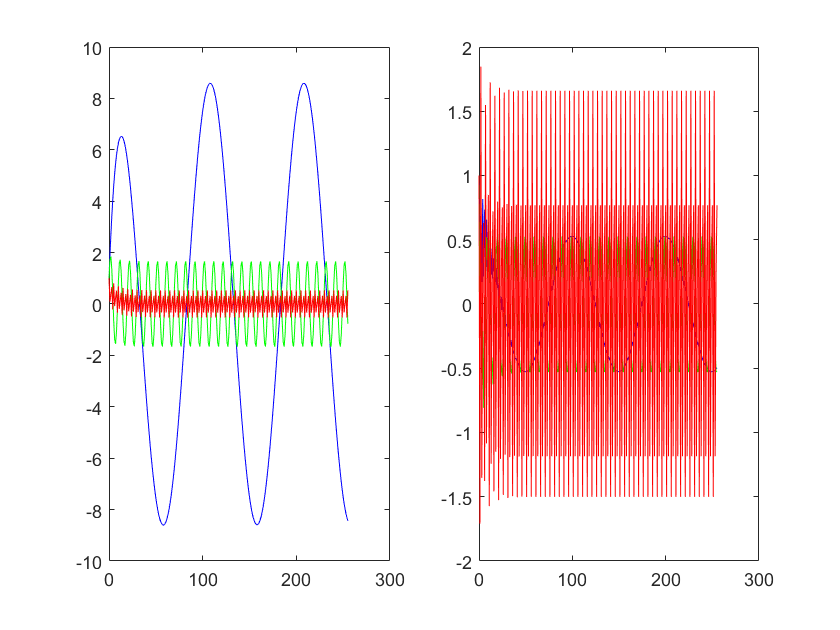


% Section 5

%freq1 response
y5 = filter(b1, a1, x3);
y6 =  filter(b2, a2, x3);

%freq2 response
y7 = filter(b1, a1, x4);
y8 =  filter(b2, a2, x4);

%freq3 response
y9 = filter(b1, a1, x5);
y10 =  filter(b2, a2, x5);

subplot(1,2,1);
plot(nv, y5, 'b', nv, y7, 'g', nv, y9, 'r'); % A = 8.5
%System 1 amplified the lowest frequency (Low Pass)

subplot(1,2,2);
plot(nv, y6, 'b', nv, y8, 'g', nv, y10, 'r'); % A = 1.5

%System 2 amplified the higher frequencies (High Pass)

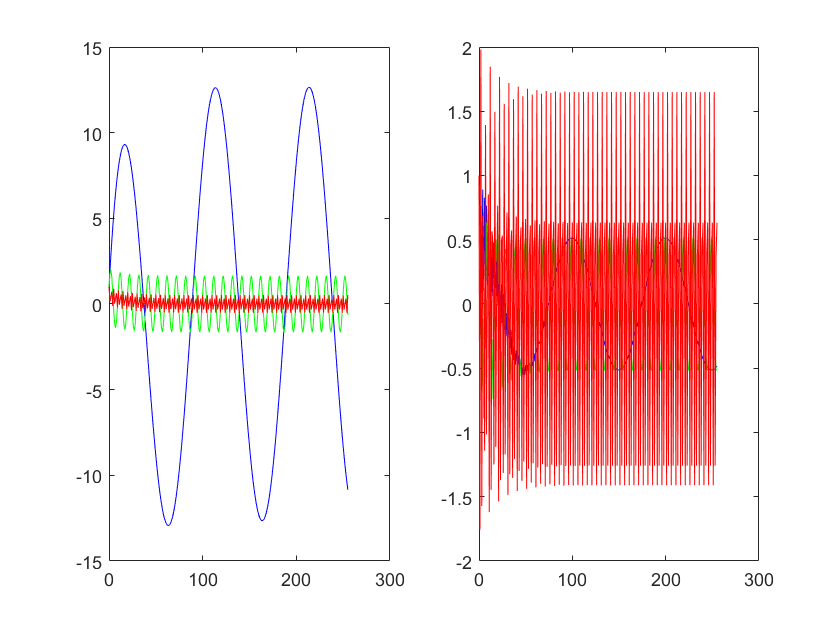

a3 = [1.0, -0.95];
b3 = 1;

a4 = [1.0, 0.95];
b4 = 1;

%freq1 response
y11 = filter(b3, a3, x3);
y12 =  filter(b4, a4, x3);

%freq2 response
y13 = filter(b3, a3, x4);
y14 =  filter(b4, a4, x4);

%freq3 response
y15 = filter(b3, a3, x5);
y16 =  filter(b4, a4, x5);

subplot(1,2,1);
plot(nv, y11, 'b', nv, y13, 'g', nv, y15, 'r'); % A = 12.5
%System 1 changed amplitude significantly

subplot(1,2,2);
plot(nv, y12, 'b', nv, y14, 'g', nv, y16, 'r'); % A = 1.4

%System 2 changed amplitude slightly

% Part 6.
alpha = 0.95; alpha2 = 0.99; w = 2*pi*0.1

w = 0.6283

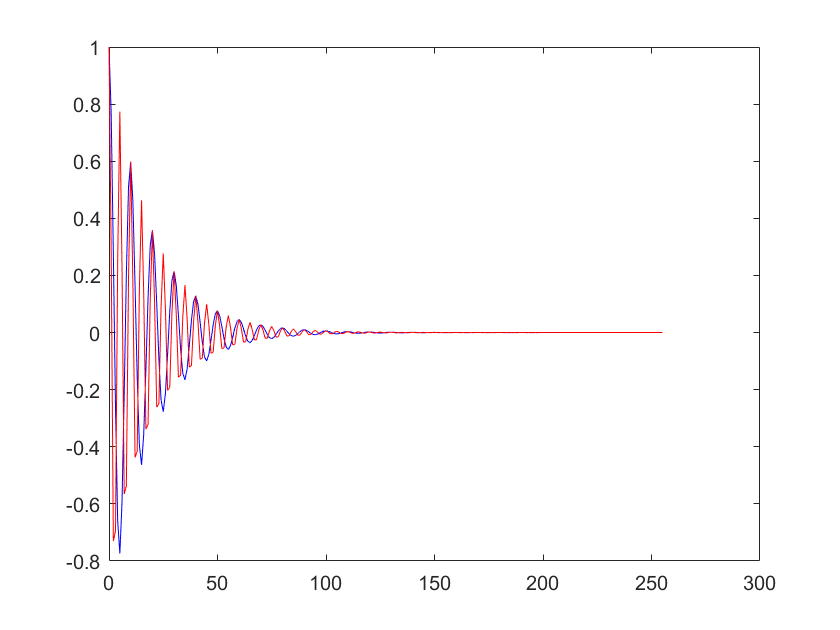


a5 = [1, -2*alpha*cos(w), alpha^2];
b5 = [1, -alpha*cos(w)];

y17 = filter(b5, a5, xi);

a6 = [1, -2*alpha*cos(w*2), alpha^2];
b6 = [1, -alpha*cos(w*2)];

y18 = filter(b6, a6, xi);

% Part 7.
subplot(1,1,1);
plot(nv, y17, 'b', nv, y18, 'r');

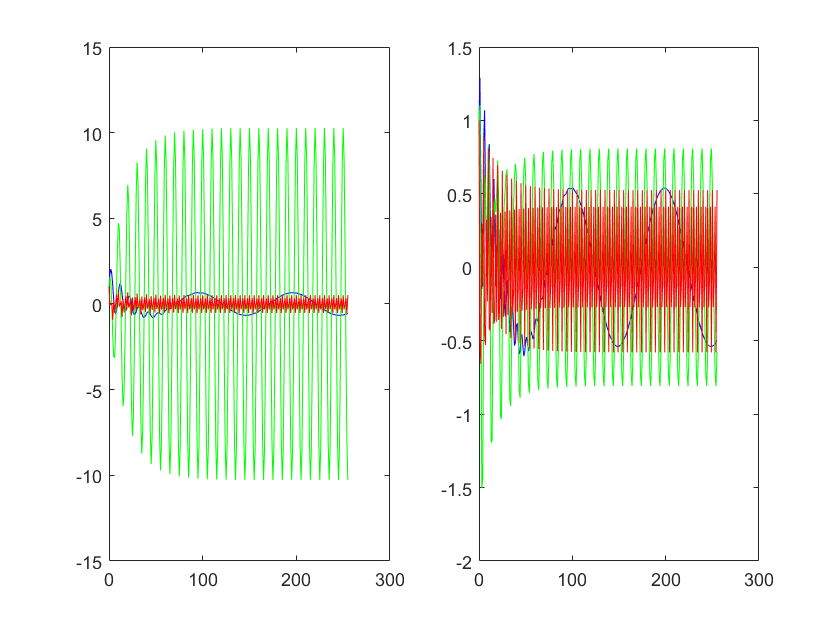


% Part 8.

%freq1 response
y19 = filter(b5, a5, x3);
y20 =  filter(b6, a6, x3);

%freq2 response
y21 = filter(b5, a5, x4);
y22 =  filter(b6, a6, x4);

%freq3 response
y23 = filter(b5, a5, x5);
y24 =  filter(b6, a6, x5);

subplot(1,2,1);
plot(nv, y19, 'b', nv, y21, 'g', nv, y23, 'r'); % 


subplot(1,2,2);
plot(nv, y20, 'b', nv, y22, 'g', nv, y24, 'r'); % 

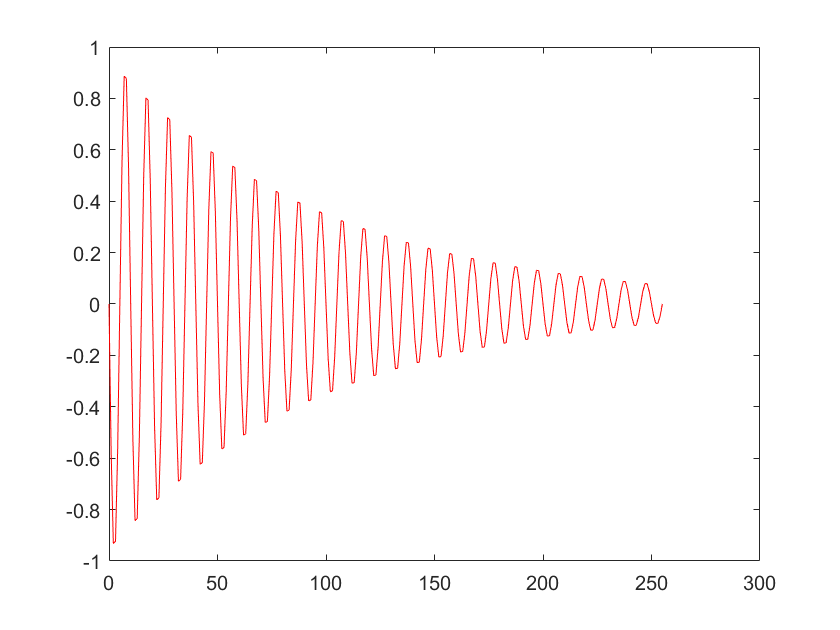

% Part 9.

a6 = [1, -2*alpha2*cos(w), alpha2^2];
b6 = [1, -alpha2*cos(w)];

y19 = filter(b6, a6, xi);

a7 = [1, -2*alpha2*cos(w*2), alpha2^2];
b7 = [1, -alpha2*cos(w*2)];

y20 = filter(b7, a7, xi);

% Part 10
subplot(1,1,1);
plot(nv, y19, 'r', nv, y20, 'b');

% Square response
y21 = filter(b6, a6, xs);
y22 =  filter(b7, a7, xs);

subplot(1,1,1);
plot(nv, y21, 'r', nv, y22, 'b');

%Part 12

a7 = [1, -2*alpha2*cos(w), alpha2^2];
b7 = [0, -alpha2*sin(w)];

y23 = filter(b7, a7, xi);

subplot(1,1,1);
plot(nv, y23, 'r');

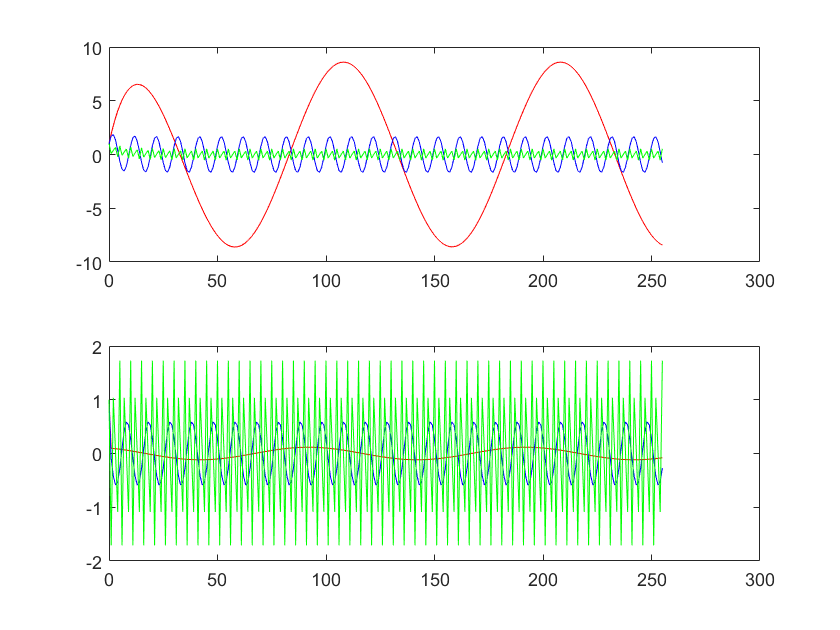

% Cascade Connection of Two First Order Systems

% Part 15

a8 = [1.0, -0.9];
b8 = 1;

a9 = 1;
b9 = [1.0, -0.9];


y24 = filter(b8, a8, xi);
y25 = filter(b9, a9, xi);

y26 = filter(b8, a8, xs);
y27 = filter(b9, a9, xs);


subplot(2,1,1);
plot(nv, y24, 'r', nv, y25, 'b');
subplot(2,1,2);
plot(nv, y26, 'r', nv, y27, 'b');

% Part 16

y28 = filter(b8, a8, x3);
y29 = filter(b9, a9, x3);

y30 = filter(b8, a8, x4);
y31 = filter(b9, a9, x4);

y32 = filter(b8, a8, x5);
y33 = filter(b9, a9, x5);

subplot(2,1,1);
plot(nv, y28, 'r', nv, y30, 'b', nv, y32, 'g');
subplot(2,1,2);
plot(nv, y29, 'r', nv, y31, 'b', nv, y33, 'g');

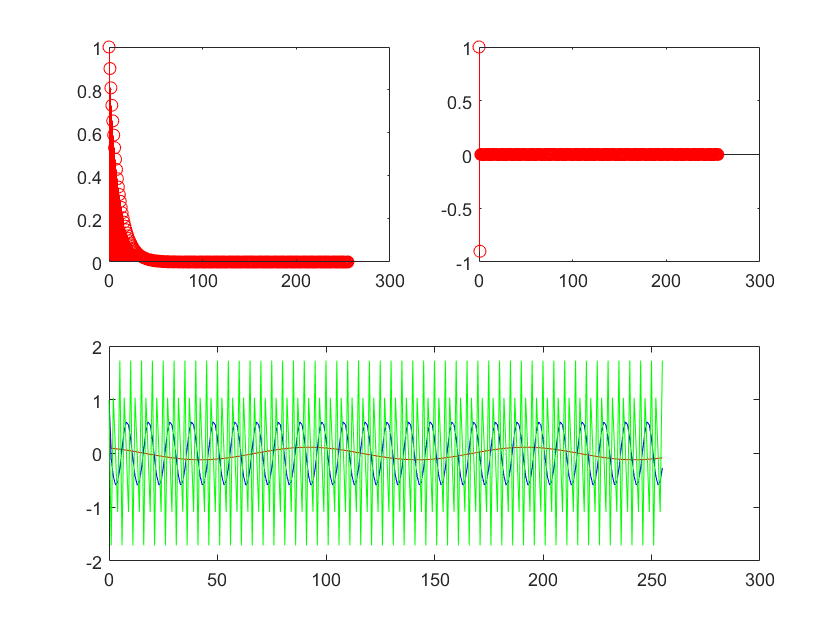

% Part 17

h1 = filter(b8, a8, xi);
h2 = filter(b9, a9, xi);
h3 = filter(b9, a9, h1);
h4 = filter(b8, a8, h2);

subplot(2,2,1);
stem(nv, h1, 'r');

subplot(2,2,2);
stem(nv, h2, 'r');

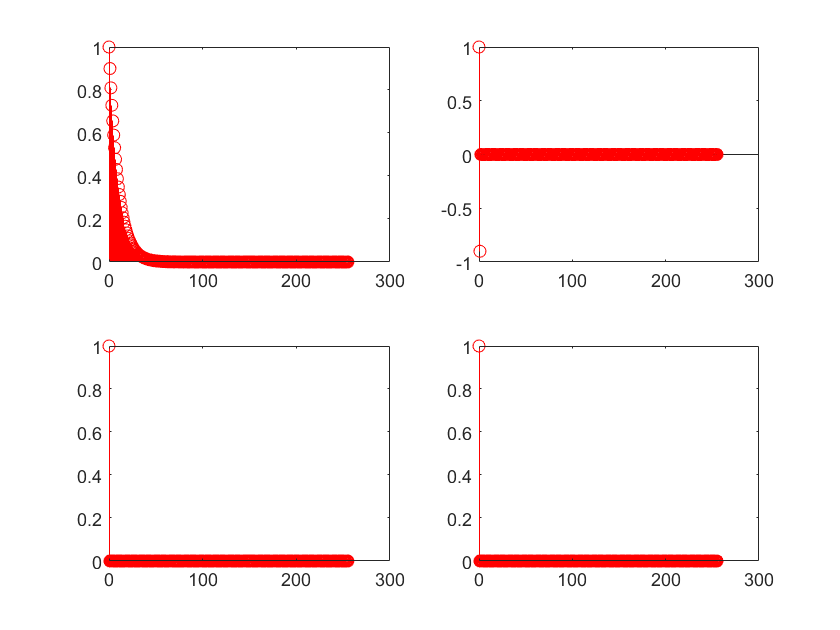


subplot(2,2,3);
stem(nv, h3, 'r');

subplot(2,2,4);
stem(nv, h4, 'r');